ALT_st.name='ALT'; 
ALT_st.lat=82.50; %82.4991455078;
ALT_st.lon=-62.34; %-62.3415260315;
ALT_st.alt=210;
ALT_st.env='A';
ALT_st.footp='A';


ALT_rd2=read_betsy('alt_2004_2017',ALT_st.name);


ALT_rd=read_betsy('alt_2004_2018_longformat',ALT_st.name);

datevec(ALT_rd.Time(1))

ans =         2004           3          19           0           0           0


datevec(ALT_rd.Time(end))

ans =         2019           1           1           0           0           0


ALT_rd.U0_S11(ALT_rd.U0_S11==99999.999)=NaN;
ALT_rd.U_S11(ALT_rd.U_S11==99999.999)=NaN;
ALT_rd.U1_S11(ALT_rd.U1_S11==99999.999)=NaN;
prctile(ALT_rd.U_S11,[5 50 95])

ans =      0     0     0


  prctile(ALT_rd.U0_S11,[5 50 95])

ans =          0    4.5000   22.5317


  prctile(ALT_rd.U1_S11,[5 50 95])

ans =          0    4.7386   22.6327


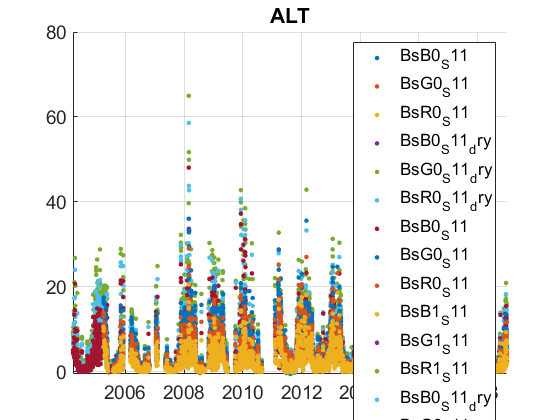

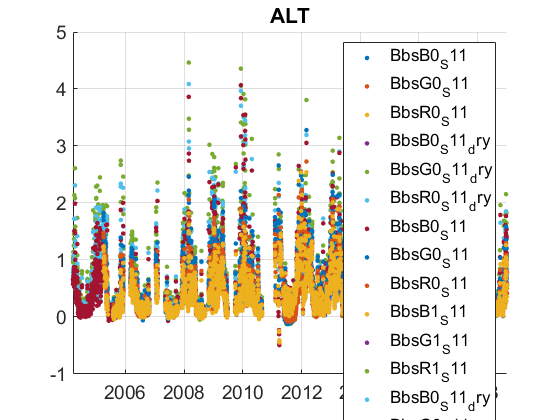

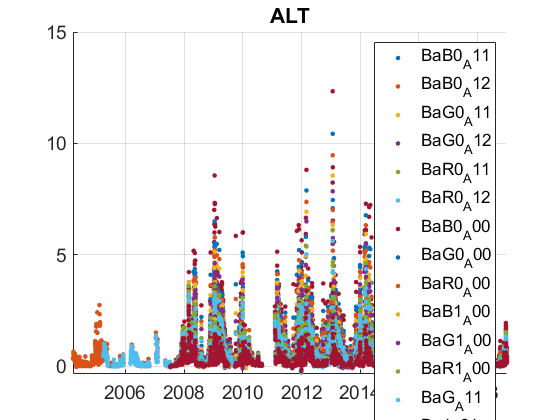

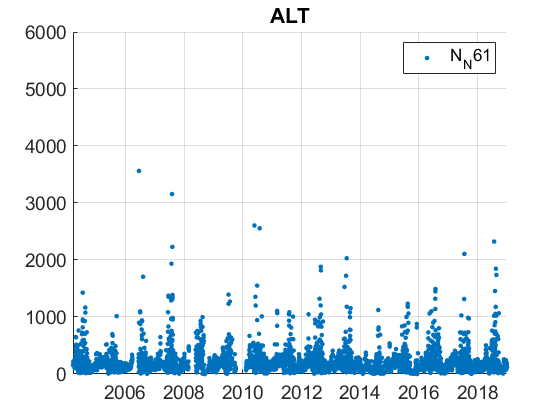

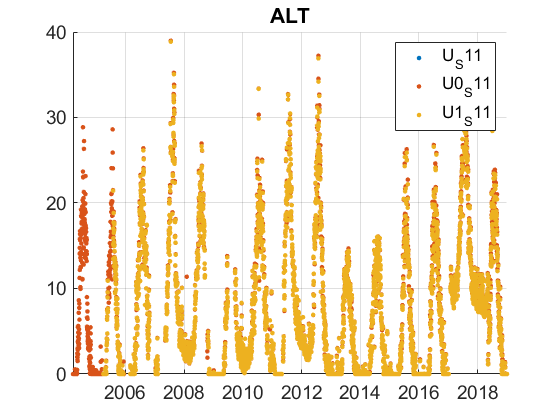

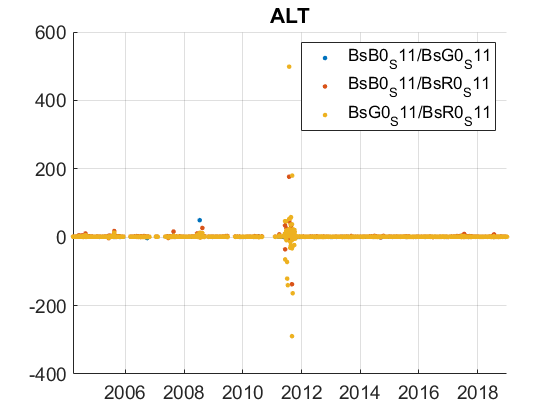

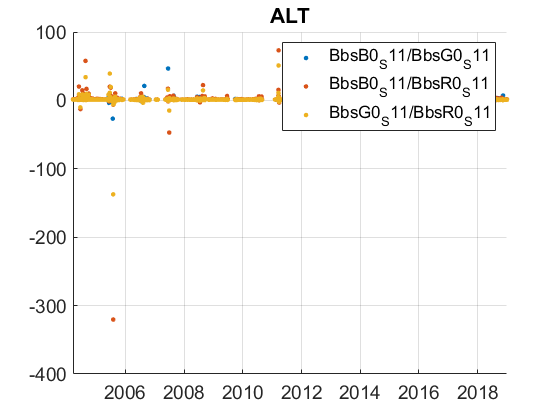

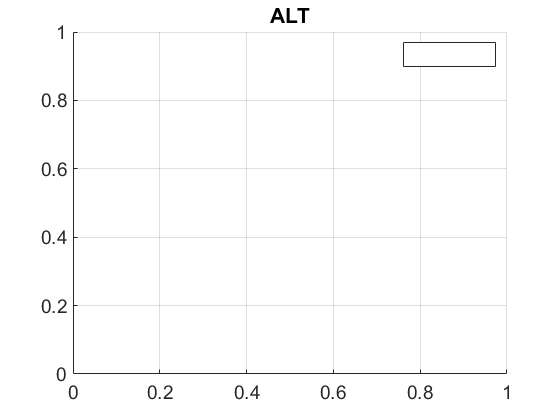

% prctile(ALT_rd.Uu1_S,[5 50 95])
plotFigControl(ALT_rd,ALT_st.name);

ALT_cal.SSA_AEG=ALT_rd.BsG0_S11./(ALT_rd.BsG0_S11+ALT_rd.Ba3_A81);

To assign to or create a variable in a table, the number of rows must match the height of the table.

ALT_cal.SSA_AER=ALT_rd.BsG0_S11./(ALT_rd.BsG0_S11+ALT_rd.Ba5_A81);
hold on;
plot(ALT_cal.Time, ALT_cal.SSA_AEG);
plot(ALT_cal.Time, ALT_cal.SSA_AER);
%compute SSA from AE31:

% 2 size cut, ok
% sc: ok, no negatives, clear seasonal cycle with max in winter
%bsp: there is negatives in summer (minima)

%N good: can be used to determine the ruptures

%SSA with AE31 has a much larger dispersion than with PSAP and CLAP

lambdaSC=[450;550;700]*ones(1,4);lambdaAE=[467;530;660]*ones(1,4);lambdaAE7=[370 470 520 590 660 880 950];

SCexclus = 145

ans = 53

ans = 2216

ans = 0

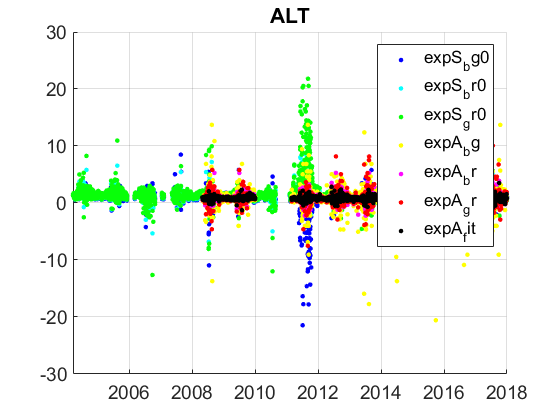

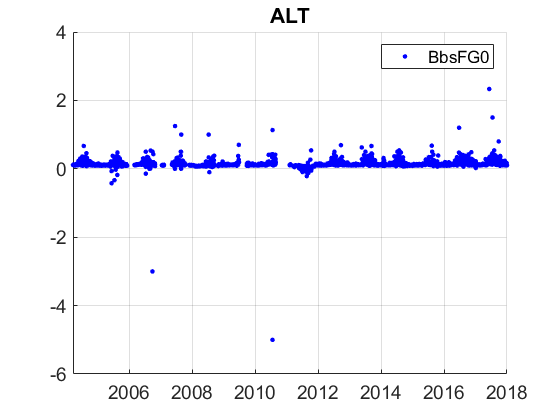

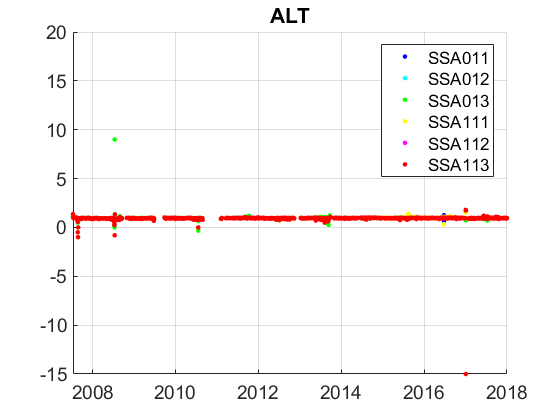

ALT_cal=compute_exp_SSA(ALT_rd,lambdaSC, lambdaAE);
plotFigControl_cal(ALT_cal, ALT_st.name);

%Questions:
%problems:

% scat: there is a lot of holes until 2011: any special reason bounded with instrumental change ?
%backscat: the maxima for both size cuts  are higher since 2008: do you have any explanation ?
% scat Exponent: there is something strange between February and December 2011: the blue-green (BG) exponent is too low and the GR and BR are too high. Do you have an explanation?
%backscattering fraction: is has a minima instead of a maxima for the same period (Feb-Dec 2011): what happened with the nephelometer ?

%abs: maxima of 1w PSAP are lower: is there any study and homogeneisation of the various absorption time series ?
%abs: PSAP (and to a less extend CLAP) has 3% of absorption values==0.  do you have an explanation ?
%AE31: why there is no data in 2010 + January and Feb 2011 ?



ALT_tr=ALT_rd;
ALT_tr.y=year(ALT_tr.Time);
%enleve une valeur de 2018
ALT_tr=ALT_tr(1:end-1,:);
% begin at the beginning of a year: 2005
%end: 2017
P=timerange('2005-01-01','2019-01-01');
ALT_tr=ALT_tr(P,:);
%trend on U0_S11 has to be done: not constant U
%dry=wet: dry to delete
%AE31 not used: delete A81, only CAPS not used: deleter A12
%if once used, the PSAP 3w has to be invalidated from May (133.5) to november 2013 (leak)
%decide to use the time series with the max of CAPS due to better SSA: delete A11
names=fieldnames(ALT_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"U1";"U_";"N"]) | endsWith(names,["T";"dry";"A81";"A12";"A11"]);
N=names(c);
for i=1:length(N)
    ALT_tr.(N{i})=[];
end
names=fieldnames(ALT_tr);
%scat PM1 begin later in April 2005 __> time series since 2006 only
%abs: PM10 since 2005 and PM1 only since 2006 also
p1=timerange('2005-01-01','2006-01-01');
C0=contains(names,["G1";"R1";"B1"]);
N0=names(C0);
for i=1:length(N0)
ALT_tr.(N0{i})(p1)=NaN;
end


%BaG_A11: only NaN to delete
%ALT_tr.BaG_A11=[];

%there is 2 times BsB0_S11 with the same numbers: one to delete ??? it is not the case

% one time series: BaG0a_A00 = BaG0t_A11 until end 2014 (PSAP) and in 2017(CLAP ) + BaG0_A12 from end 2014 to end 2016 (CLAP)
% PSAP is 1w until July 2007 and 3w then
% abs: two break points: July 2007 and september 2014, not really visible in the data itself.
%moreover the ratio with N does not present break points.
%from end 2007 to begin 2014, the minima is a little bit higher (probably not important)
%abs PSAP and CLAP==0 to put as NaN?? not sure!

% ask for the date (2 feb 2011-1.1 2012?) and invalidate expS and BbsGF for that period. It is the backscatter that has problem: invalidate also the backscatter and the G and R scatter. The blue scatter seems to be the best: use blue for the trend ?
%INVALIDATE ALSO BLUE ??
p2=timerange('2011-02-02','2012-01-01');
ALT_tr.BsG0_S11(p2)=NaN;
ALT_tr.BsR0_S11(p2)=NaN;
ALT_tr.BbsB0_S11(p2)=NaN;
ALT_tr.BbsG0_S11(p2)=NaN;
ALT_tr.BbsR0_S11(p2)=NaN;

ALT_tr.BsG1_S11(p2)=NaN;
ALT_tr.BsR1_S11(p2)=NaN;
ALT_tr.BbsB1_S11(p2)=NaN;
ALT_tr.BbsG1_S11(p2)=NaN;
ALT_tr.BbsR1_S11(p2)=NaN;
% abs: ask if my data are the homogenized one. If they are, I’m not sure. Most homogene time series=BaG0T_A11: probably ok, some doubt 
%there is not much difference between A11 (mostly PSAP) and A00 (mostly CAPS): usse CAPS since SSA seems better with CAPS

 ALT_cal2=compute_exp_SSA(ALT_tr,lambdaSC, lambdaAE);
% % correct blue scat to green to compute SSA:


% ALT_tr.expA0_bg_A00=real(-log(ALT_tr.BaB0a_A00./ALT_tr.BaG0a_A00)./log(lambdaAE(1)/lambdaAE(2)));
% ALT_tr.expA0_bg_A11=real(-log(ALT_tr.BaB0t_A11./ALT_tr.BaG0t_A11)./log(lambdaAE(1)/lambdaAE(2)));
% ALT_tr.SSA0B_A11= ALT_tr.BsB0_S11./(ALT_tr.BsB0_S11+ALT_tr.BaB0t_A11);
% ALT_tr.SSA0B_A00=ALT_tr.BsB0_S11./(ALT_tr.BsB0_S11+ALT_tr.BaB0a_A00);
% ALT_tr.SSA1B_A11=ALT_tr.BsB1_S11./(ALT_tr.BsB1_S11+ALT_tr.BaB1t_A11);
% ALT_tr.SSA1B_A00=ALT_tr.BsB1_S11./(ALT_tr.BsB1_S11+ALT_tr.BaB1a_A00);
%plotFigControl_cal(ALT_cal2,ALT_st);
% 	SSA: use BaGOt_A11 and blue scat 

%AE31: from April 2008: time series since 2009 to test, with exponent

%AE31 abs exp: the best one if the fit.

%scat exponent is higher in 2017 after a hole for bg --> also use either gr 

%there is a problem for ExpA with the green --> use expA_br
ALT_cal2.expA_bg1=[];
ALT_cal2.expA_gr1=[];
ALT_cal2.expA_bg0=[];
ALT_cal2.expA_gr0=[];
%Further questions: Mai-November 2013: abs to invalidate ?
ALT_tr=outerjoin(ALT_tr,ALT_cal2);
 ALT_tr.SSA011= ALT_tr.BsB0_S11.*(450/550)./(ALT_tr.BsB0_S11.*(450/550)+ALT_tr.BaB0_A00);
 ALT_tr.SSA111=ALT_tr.BsB0_S11.*(450/550)./(ALT_tr.BsB0_S11.*(450/550)+ALT_tr.BaB0_A00);
% compute trend only on blue neph and green abs
% correct blue scat to green to compute SSA:

ALT_tr.BsG0_S11=[];
ALT_tr.BsR0_S11=[];
ALT_tr.BsG1_S11=[];
ALT_tr.BsR1_S11=[];
ALT_tr.BbsG0_S11=[];
ALT_tr.BbsR0_S11=[];
ALT_tr.BbsG1_S11=[];
ALT_tr.BbsR1_S11=[];

ALT_tr.expS_br0=[];
ALT_tr.expS_br1=[];
ALT_tr.expS_gr0=[];
ALT_tr.expS_gr1=[];

% compute only green abs
ALT_tr.BaB0_A00=[];
ALT_tr.BaB1_A00=[];
ALT_tr.BaR0_A00=[];
ALT_tr.BaR1_A00=[];


% SSA is lower at the beginning and higher and more constant with CLAP. Probably a rupture¨!

ALT_result= all_trend_STN(ALT_tr,ALT_st); 
plot_10y_in_two(ALT_result,ALT_st);

ALT_result_D=ALT_result;